clear all;
clc;
load("mnist-matlab.mat")

for i= 1:size(X_train,1)
    XTrain(:,1,1,i) = X_train(i,:);
end
for i= 1:size(X_test,1)
    XTest(:,1,1,i) = X_test(i,:);
end

classNames = categories(y_train);
numClasses = numel(classNames);
numObservations = numel(y_train);

## Parameters

parameters{1} = dlarray(initializeGaussian([1000,size(X_train,2)]));
parameters{2} = dlarray(zeros(1000,1,'single'));

parameters{3} = dlarray(initializeGaussian([1000,1000]));
parameters{4} = dlarray(zeros(1000,1,'single'));

parameters{5} = dlarray(initializeGaussian([numClasses,1000]));
parameters{6} = dlarray(zeros(numClasses,1,'single'));

## Specify Training Options

numEpochs = 10;
miniBatchSize = 2000;
plots = "training-progress";
numIterationsPerEpoch = floor(numObservations./miniBatchSize);
executionEnvironment = "auto";
learning_rate = 1e-4;

## Train Model

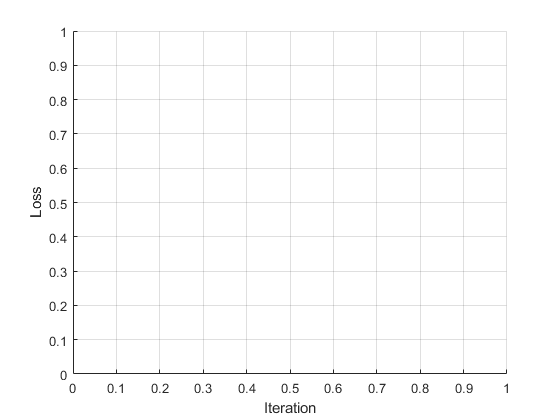

if plots == "training-progress"
    figure

    lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
    ylim([0 inf])
    xlabel("Iteration")
    ylabel("Loss")
    grid on
end


vel = [];
iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Shuffle data.
    idx = randperm(numObservations);
    XTrain = XTrain(:,:,:,idx);
    y_train = y_train(idx);
    
    % Loop over mini-batches
    for i = 1:numIterationsPerEpoch
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        
        % Read mini-batch of data and convert the labels to dummy
        % variables.
        X = XTrain(:,:,:,idx);
        
        Y1 = zeros(numClasses, miniBatchSize, 'single');
        for c = 1:numClasses
            Y1(c,y_train(idx)==classNames(c)) = 1;
        end
        
        
        % Convert mini-batch of data to dlarray.
        dlX = dlarray(X,'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
        end
        
        % get final output from model
        [dlY1, modelstages] = model(dlX,parameters);
        
        % pass output to calculate loss and gradient
        [gradients,loss] = dlfeval(@modelGradients, dlY1, Y1, parameters(5:6));
        
        % Update the network parameters using the SGDM optimizer.
        parameters = dlupdate(@updateparam, parameters, gradients, loss, modelstages, learning_rate);
        
        % Display the training progress.
        if plots == "training-progress"
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
            drawnow
        end
    end
end

Unable to perform assignment because the size of the left side is 6-by-1 and the size of the right side is 2-by-1.

Error in deep.internal.recording.containerfeval>iProcessCell_Nout_Nin (line 231)
    AllVarArgs(:,input) = varargin{input}(:);

Error in deep.internal.recording.containerfeval>iDispatch_Nout_Nin (

## Test Model

dlXTest = dlarray(XTest,'SSCB');
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXTest = gpuArray(dlXTest);
end
dlYPred = model(dlXTest, parameters);

Evaluate the classification accuracy.

[~,idx] = max(extractdata(dlYPred),[],1);
labelsPred = categorical(classNames(idx));
accuracy = mean(labelsPred==y_test)

## Model Function

function [dlYf, stages] = model(dlX,parameters)


% Fully connect + sigmoid
weights = parameters{1};
bias = parameters{2};
dlY1 = fullyconnect(dlX,weights,bias);
dlY1 = sigmoid(dlY1);
stages{1} = dlY1;
% Fully connect + sigmoid
weights = parameters{3};
bias = parameters{4};
dlY2 = fullyconnect(dlY1,weights,bias);
dlY2 = sigmoid(dlY2);
stages{2} = dlY2;
% Fully connect + softmax
weights = parameters{5};
bias = parameters{6};
dlY3 = fullyconnect(dlY2,weights,bias);
dlYf = softmax(dlY3);

end

## Model Gradients Function

function [gradients,loss] = modelGradients(out,T1,parameters)
lossLabels = crossentropy(out,T1);

loss = lossLabels;
gradients = dlgradient(lossLabels,parameters);

end

## Weights Initialization Function

The `initializeGaussian` function samples weights from a Gaussian distribution with mean 0 and standard deviation 0.01.

function parameter = initializeGaussian(sz)
parameter = randn(sz,'single').*0.01;
end

## **Parameter Update Function**

function updated = updateparam(parameters, grads, loss, stages, learning_rate, input)

del_a{2} = loss*stages{2};
del_a{2} = 
end

## Sigmoid Derivative Function

function Y = sigmoid_derive(X)
 Y = sigmoid(X).*(1-sigmoid(X));
end 